# Algoritmos Numéricos por Computadora

# Primer parcial - Otoño 2020

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 1 antes de las 10am.

Cada pregunta vale 5 puntos.

#### Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

#### El artículo 29 del Reglamento de Alumnos establece que "se calificará como no acreditada (N.A.) cualquier materia cuando el alumno incurra en alguna práctica fraudulenta".

 1. Determina el numero positivo más pequeño (spsn) que puede representarse de manera exacta en Matlab

format long
minF=0;
minExponente=1-1023;
minPositivo=(1+minF)*2^minExponente

minPositivo =     2.225073858507201e-308


2. Tipos de errores (redondeo, underflow y overflow)

2a) ¿Qué tipo de error se tiene si un cálculo da como resultado un número menor que spsn?

% Underflow

2b) ¿Qué resultado regresa Matlab en este caso?

% 0

2c) ¿Qué tipo de error se tiene si un cálculo da como resultado un número mayor que 1.797693134862316e+308 (ej: *realmax + eps(realmax)*)?

% Overflow

2d) ¿Qué resultado regresa Matlab en este caso?

% Inf

2e)  Considera el siguiente fragmento de código:

ms = 12;
n = 35;
e = 5;
d = 29;
c = mod(ms^e,n);
format long
c^d

ans =      4.819685721067509e+35


format
mr = mod(c^d,n);
if ms~=mr, disp('error de ...'), end

error de ...


¿Qué tipo de error se tiene al calcular c^d? (El resultado debería ser 4.81968572106750915091411825223071697e+35)

% Error de redondeo

3. Demuestra que en el algoritmo de falsa posición (interpolación lineal) el valor de $x_r$ en la siguiente iteración se calcula con la siguiente fórmula.

Pega aquí tu respuesta.

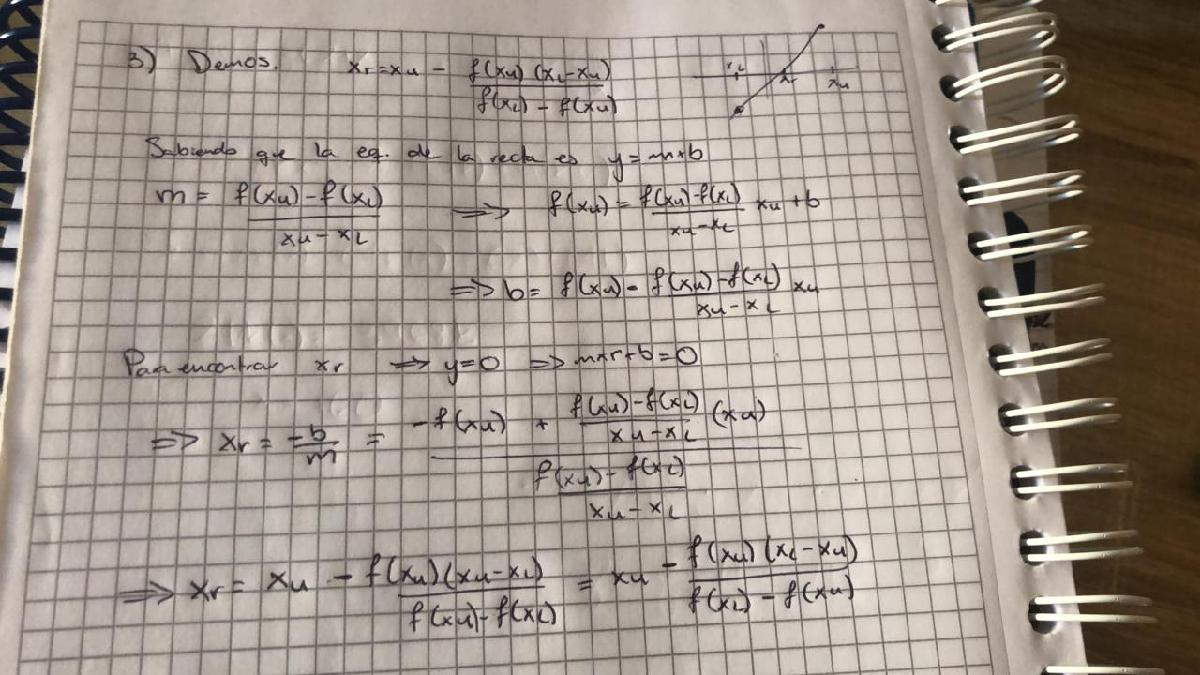

4. Demuestra que el mínimo de una parábola definida por los tres puntos $r,s,t$ se encuentra en

Pega aquí tu respuesta.

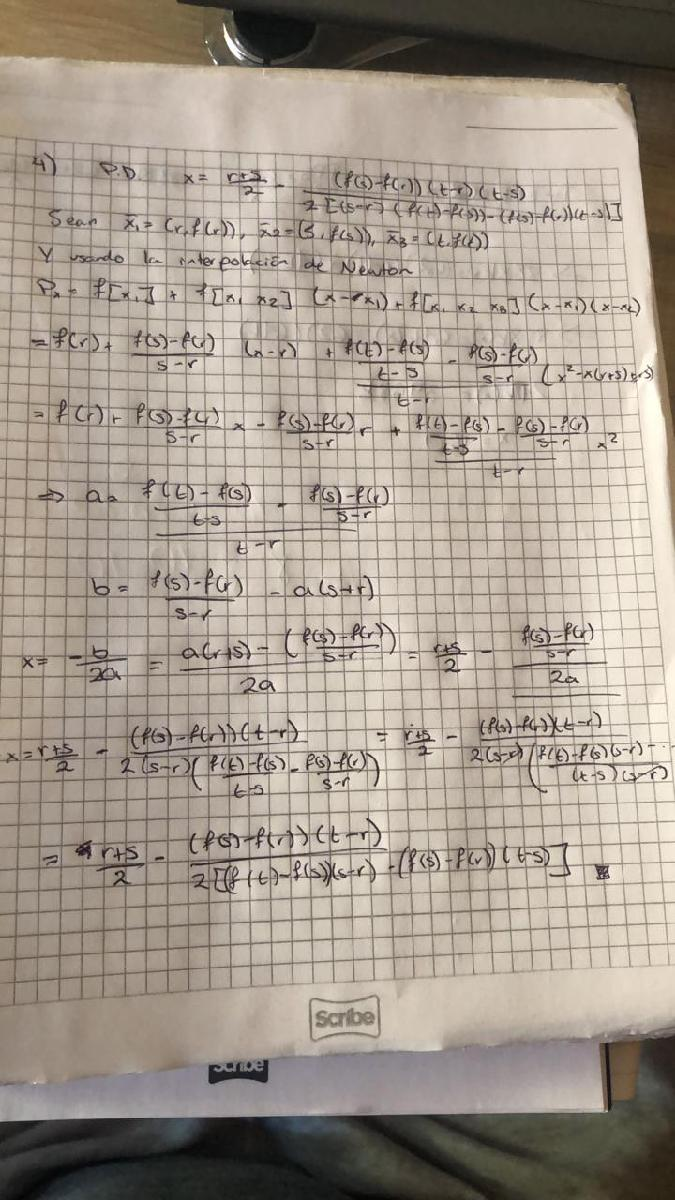

5a. Usa la función *puntoFijo* (que debes codifícar al final del script) para encontrar la primera raíz no trivial de $\sin \left(x\right)=x^2$ donde $x$ está dada en radianes. Usa como primera aproximación $x=0\ldotp 7$.

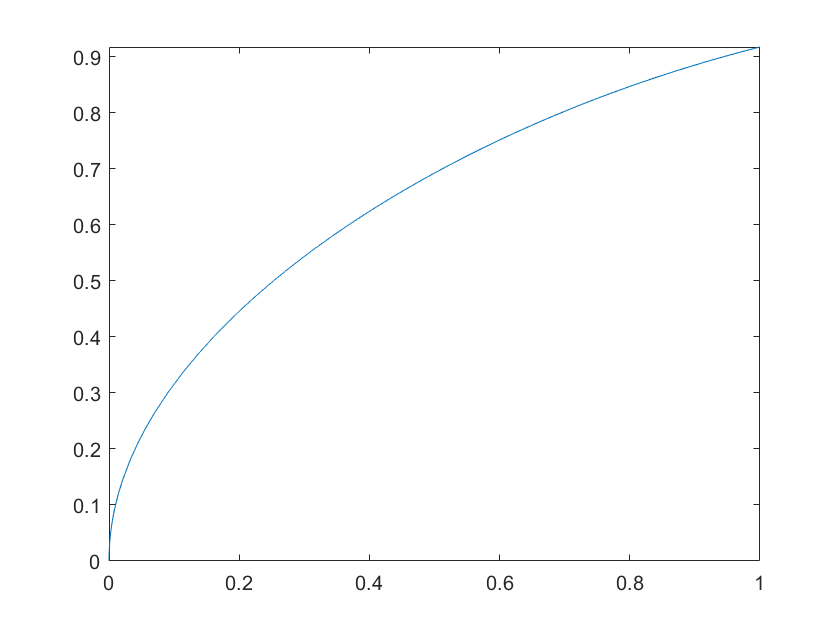

x = 0.8767

i = 36

g=@(x) sqrt(sin(x));
fplot(g,[0,1]);

6. Una carga total $Q$ está distribuida uniformemente alrededor de un conductor con forma anillo de radio $a$. Una carga $q$ se localiza a una distancia $x$ del centro del anillo. 

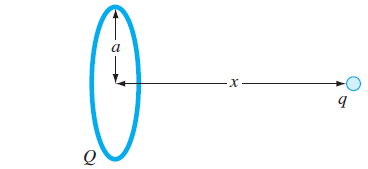

La fuerza ejercida en la carga por el anillo está dada por 

donde where $e_0 =8\ldotp 9\times {10}^{-12} \;\frac{C^2 }{Nm^2 }$ .

a) Grafica la fuerza $F$ considerando que las cargas $q$ y $Q$ son de $2\times {10}^{-5} \;C$ y el radio $a$ del anillo es de 0.85 m. Grafica en el intervalo [0 , 2].

e0=8.9e-12;
q=2e-5;
Q=2e-5;
a=0.85;
f=@(x) 1/(4*pi*e0) * (x*q*Q)/(x.^2+a.^2).^(3/2);
fplot(f,[0,2]);

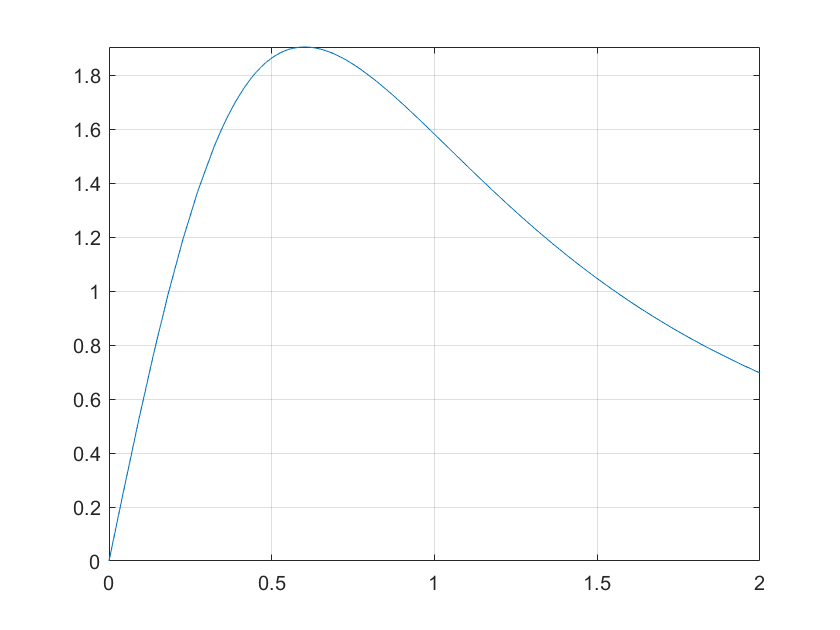

grid on;

b) Determina visualmente un intervalo (más pequeño) en el que se encuentra la raíz.

fplot(f,[-0.5,0.5]);

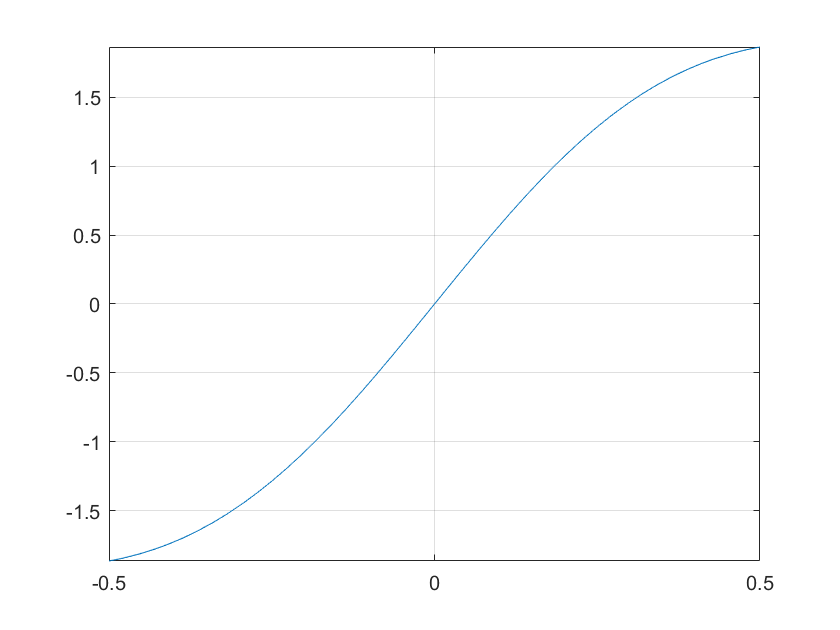

grid on;

c) Encuentra la distancia $x$ donde la fuerza es igual a 1.25 N. Usa cualquier método.

g=@(x) f(x)-1.25;
[x,i]=interpolacion(g,0,0.5)

x = 0.2410

i = 25

7. Siguiendo con el problema anterior.

a) Usa la función *newtonRaphsonOptimizacionDF* (problema 9) para determinar la distancia $x$ donde la fuerza es máxima.  

(Plan B - usa el algoritmo de proporción áurea; Plan C - usa fminsearch)

[x,i,min]=newtonRaphsonOptimizacionDF(f,0.5)

x = 0.6010

i = 1000

min = logical
   0


b) ¿Cuánto vale la fuerza máxima?

f(x)

ans = 1.9053

5b. Codifica aquí, de manera **estructurada** y **eficiente**, la función *puntoFijo* que calcula una raíz de la función$f\left(x\right)$mediante el algoritmo de (iteración simple de) punto fijo (o substitución sucesiva).

La fórmula de este algoritmo se obtiene reordenando la ecuación$f\left(x\right)=0$ de tal manera que$x$ quede en el lado izquierdo de la ecuación: $x=g\left(x\right)$. 

La ecuación $x=g\left(x\right)\;$proporciona una fórmula para predecir un nuevo valor de $x$ en función de un valor previo de $x$. Entonces, dado un valor aproximado de la raíz  $x_i$ la formula puede usarse para calcular una nueva aproximación $x_{i+1}$ de acuerdo a la fórmula iterativa: $x_{i+1} =g\left(x_i \right)$.

function [x, i] = puntoFijo(g,x)
% Computes fixed point x=g(x)
% Input: function handle g; first aproximation x
% Output: Approximate solution x; number of iterations performed i
% Este algoritmo converge si abs(g'(x))<1
    gsym=sym(g);
    dgs=diff(gsym);
    dg=matlabFunction(dgs);
    if abs(dg(x))>=1, error('No converge'), end
    xp=x;
    x=g(x);
    i=1;
    MAX=1000;
    while abs((x-xp)/x)>eps && abs(dg(x))<1 && i<MAX
        xp=x;
        x=g(x);
        i=i+1;
    end

end

MÉTODO DEL EJERCICIO 6: Interpolación lineal

function [x,i]=interpolacion(f,x0,x1)
    if f(x0)*f(x1)>0, error('f(a) y f(b) deben tener distinto signo'), end
    xprev=x1;
    xder=x0;
    xizq=x1;
    x=xder-f(xder)*(xder-xizq)/(f(xder)-f(xizq));
    i=1;
    MAX=1000;
    while abs((x-xprev)/x)>eps && f(x)~=0 && i<MAX
        xprev=x;
        x=xder-f(xder)*(xder-xprev)/(f(xder)-f(xprev));
        i=i+1;
    end
end

8. Codifica aquí, de manera **estructurada**, **modular** y **eficiente**, la función newtonRaphsonOptimizacionDF que calcula un punto crítico de una función$f\left(x\right)$. La función debe aproximar las derivada de la función $f\left(x\right)$ utilizando las siguientes diferencias finitas centradas con error de $O\left(h^2 \right)$:


$$\frac{\mathrm{d}}{\mathrm{d}x}f=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$



$$\frac{{\mathrm{d}}^2 }{\mathrm{d}x^2 }f=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$$


Usa h = abs(x/1e5).

function [x,i,min] = newtonRaphsonOptimizacionDF(f,x)
% Computes critical point x of f
% Input: function handle f; first aproximation x
% Output: Approximate solution x; 
%         number of iterations performed i
%         boolean min indicating if x is a minimum
    h = abs(x/1e5);
    dfs=(f(x+h)-f(x-h))/(2*h);
    dfs2=(f(x+h)-2*f(x)+f(x-h))/h.^2;
    xp=x;
    MAX=1000;
    i=0;
    x=xp-dfs/dfs2;
    while abs((x-xp)/xp)>eps && i<MAX
        dfs=(f(x+h)-f(x-h))/(2*h);
        dfs2=(f(x+h)-2*f(x)+f(x-h))/h.^2;
        xp=x;
        x=xp-dfs/dfs2;
        i=i+1;
    end
    
    min=true;
    if(dfs2<0)
        min=false;
    end
end